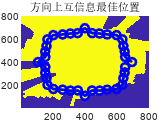



% 参数准备
xI = [x0(1),x0(2)-1];
xF = [row1(4),x0(1)];


    %% 生成均匀间隔的角度集合
    numAngles = 36;  % 设定角度数量（如每20度一个，共36个）
    angles = linspace(0, 2*pi, numAngles + 1);  
    angles(end) = [];  % 去掉2*pi，避免重复
    
    Boundary = zeros(numAngles,1);
    for i = 1:numAngles
        [Boundary(i), ~] = Find_Boundary(angles(i),LSM,BSloc);
    end

% 设置起点startPos和终点destPos



startPos  = xI;
destPos   = xF;

measurementPositions = Calculate_meas_loc_eachang(BSloc(1:2),I_Lphi_Mxn,angles,Boundary);
figure;
hold on;
imagesc(LSM');
plot(measurementPositions(:,1), measurementPositions(:,2), 'bo-', 'LineWidth', 2);
title('方向上互信息最佳位置');
xlim([1,800]);
ylim([1,800]);

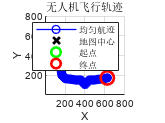


stepLength = 4;  % 固定飞行间隔，适应400范围

% 生成均匀间隔的航迹点
resampledWaypoints = generateUniformTrajectory(BSloc(1:2), startPos, destPos, measurementPositions, stepLength);

% 绘图展示结果
figure; hold on; grid on;
plot(resampledWaypoints(:,1), resampledWaypoints(:,2), 'bo-', 'LineWidth', 1);
plot(BSloc(1), BSloc(2), 'kx', 'MarkerSize', 12, 'LineWidth', 2);
plot(startPos(1), startPos(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(destPos(1), destPos(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
legend('均匀航迹','地图中心','起点','终点');
title('无人机飞行轨迹');
xlabel('X');
ylabel('Y');
axis equal;
xlim([1,800]);
ylim([1,800]);

## 更新LSM

numMeas = size(resampledWaypoints,1);

for n = 1:numMeas
    LSM_prior = LSM_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    
    [updated_gridn,LSM_posterior] = Update_LSM(LSM_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');
end








## Mutual Information Update



[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

## Iterative trajectory design

% 迭代寻找轨迹，直到满足一定条件结束无人机飞行。

%% 更新初始位置和目的地，寻找寻找I_Lphi_Mxn中的最大值。
for i = 1:3
xI = xF;
maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
xF = [row1(1),col1(1)];% 可能会有几个最大值。
[measurementPositions,resampledWaypoints] = Route_Planner_MMI(I_Lphi_Mxn,xI,xF,LSM,BSloc);


numMeas = size(resampledWaypoints,1);
updated_gridn = [];
for n = 1:numMeas
    LSM_prior = LSM_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    
    [updated_gridn,LSM_posterior] = Update_LSM(LSM_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');
end

[NUM_upa,~] = size(updated_grid);
for j = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(j,1),updated_grid(j,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

end

## 插值，LSM地图补全

LSM_upa_iter = zeros(size(updated_grid,1),1);
for i = 1:size(updated_grid,1)
    LSM_upa_iter(i) = LSM_posterior(updated_grid(i,1),updated_grid(i,2));
end

Predic_Loc =zeros(800*800,2)

Predic_Loc =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


for i = 1:800
    disp(i)
    for j = 1:800 
        Predic_Loc((i-1)*800 + j,:) = [i,j];
    end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



[~,idx1,~] = intersect(Predic_Loc,updated_grid,'rows'); % [common_rows,idx1,idx2] = intersect(ARRAY1,ARRAY2,'rows')
Predic_Loc(idx1,:) = [];


LSM_Vec_iter = IDW_KNN(updated_grid,LSM_upa_iter,Predic_Loc);
LSM_est_iter = ones(800,800);
Loc = [updated_grid;Predic_Loc];
Val = [LSM_upa_iter;LSM_Vec_iter];

for i = 1:size(Loc,1)
        LSM_est_iter(Loc(i,1), Loc(i,2)) = Val(i);
end

## Plotting

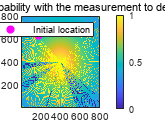


figure;
imagesc(LSM_posterior');
set(gca,'YDir','normal');
colorbar;
title('Posterior LoS probability with the measurement to destination');
hold on;
scatter(x0(1),x0(2),'magenta*','LineWidth',2);
legend('Initial location');

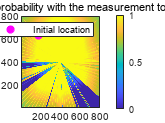


figure;
imagesc(LSM_est_iter');
set(gca,'YDir','normal');
colorbar;
title('The estimated LoS probability with the measurement to destination');
hold on;
scatter(x0(1),x0(2),'magenta*','LineWidth',2);
legend('Initial location');

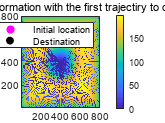



figure;
imagesc(I_Lphi_Mxn');
set(gca,'YDir','normal');
colorbar;
title('Updated Mutual Information with the first trajectiry to destination');
hold on;
scatter(xI(1),xI(2),'magenta*','LineWidth',2);
scatter(xF(1),xF(2),'filled','black','LineWidth',2);
legend('Initial location','Destination');